newpoints = 1;

points =     2.0243   -2.3595
   -0.5100   -1.3216
   -0.6361    0.3179
    0.1380   -0.7107
    0.7770    0.6224
    0.6474   -0.4256
    1.0486    0.6607
    2.5088    1.0635
    1.1569    0.0530
   -1.2884   -0.3712
   -0.7578   -0.5640
    0.5551   -0.5568
   -0.8951   -0.4093
   -0.1609    0.4093
   -0.9526    0.3173


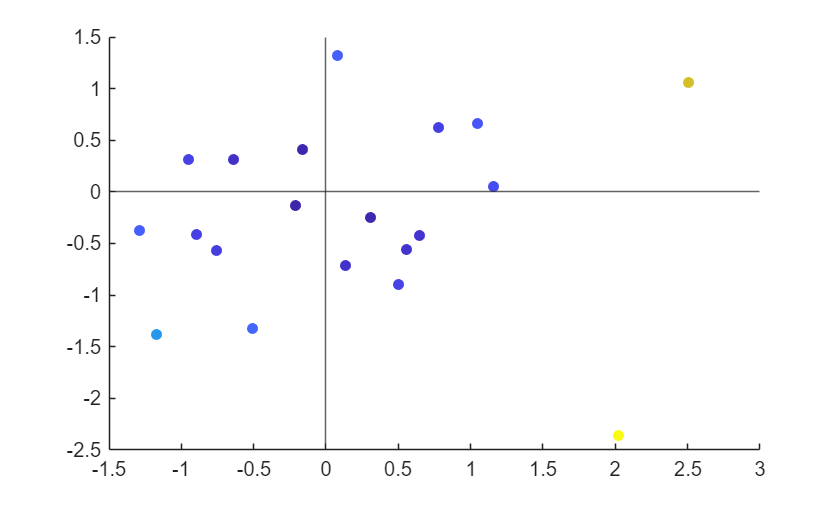

if newpoints == 1
    len = 20;
    points = zeros(len,2);
    for i = 1:len
        points(i,:) = [randn(1), randn(1)];
    end
    points
    scatter(points(:,1),points(:,2),30,[points(:,1).^2 + points(:,2).^2],"filled")
    xline(0)
    yline(0)
    writematrix(points,'randomPoints.txt')
else
    points = readmatrix('randomPoints.txt')
end

% first tree
points = readmatrix('randomPoints1.txt');
values = points(:,1).^2 + points(:,2).^2

values =     0.9060
    0.6276
    1.2134
    0.2121
    0.9699
    0.8236
    1.0373
    4.7645
    1.7608
    1.1026
    1.2520
    0.1040
    0.2510
    0.8961
    5.8577


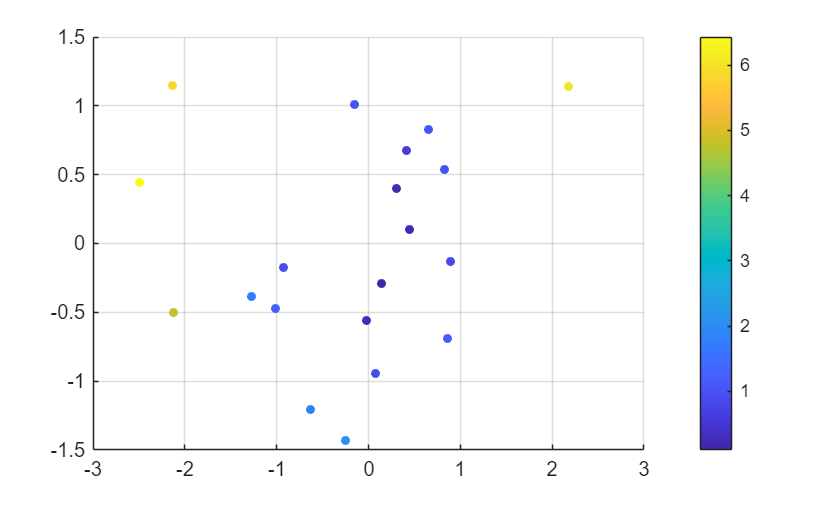

scatter3(points(:,1),points(:,2),values,20,values,"filled")
hold on
clbr = colorbar;
view([360.00 90.00])
hold off

rtree = fitrtree([points(:,1),points(:,2)],values)

rtree =   RegressionTree
             ResponseName: 'Y'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 20


  Properties, Methods


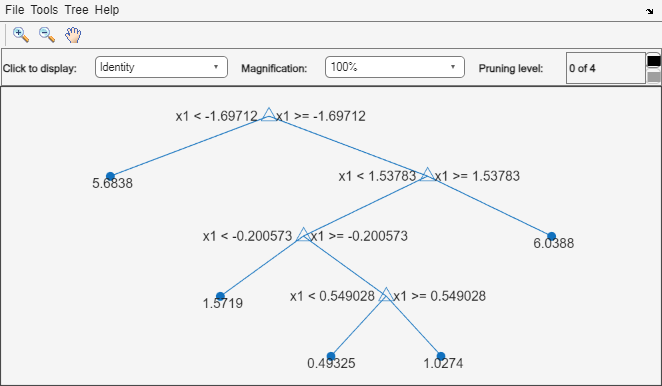

view(rtree,'Mode','graph')

view(rtree)


Decision tree for regression
1  if x1<-1.69712 then node 2 elseif x1>=-1.69712 then node 3 else 1.92559
2  fit = 5.6838
3  if x1<1.53783 then node 4 elseif x1>=1.53783 then node 5 else 1.26238
4  if x1<-0.200573 then node 6 elseif x1>=-0.200573 then node 7 else 0.963854
5  fit = 6.03882
6  fit = 1.57189
7  if x1<0.549028 then node 8 elseif x1>=0.549028 then node 9 else 0.687476
8  fit = 0.49325
9  fit = 1.02737



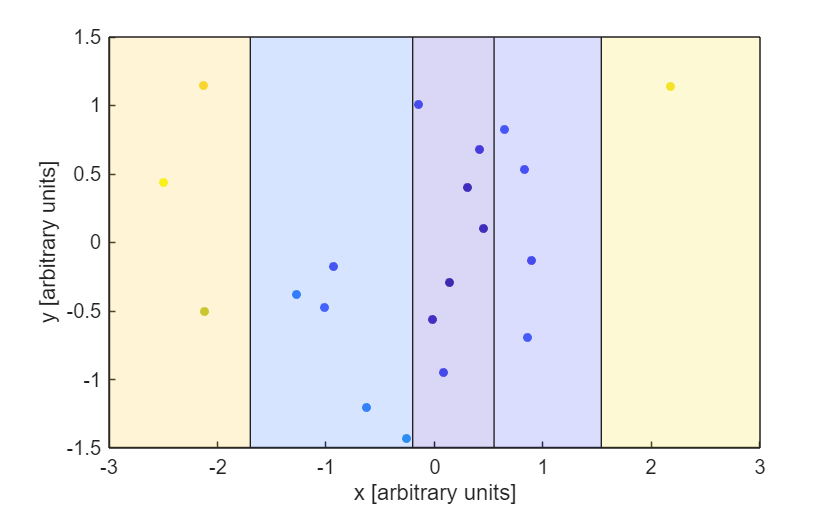

% manuall plotting of rtree on a scatter to show efficacy
scatter(points(:,1),points(:,2),20,values,"filled")
hold on 
xlim([-3,3])
ylim([-1.5 1.5])
ax = gca();
cmap = ax.Colormap;
%xline(-1.69712,'k','root','LabelVerticalAlignment','top','LabelOrientation','horizontal')
     % min   max      max   min |  min  min max max  
patch([-3 -1.69712 -1.69712 -3], [-1.5 -1.5 1.5 1.5], getcolour(5.6838,cmap,values),'FaceAlpha',.2)%,'EdgeAlpha',0)
%yline(1.07312)
patch([1.53783 3 3 1.53783], [-1.5 -1.5 1.5 1.5], getcolour(6.0338,cmap,values),'FaceAlpha',.2)
%xline(-0.200573)
patch([-1.69712 -0.200573 -0.200573 -1.69712], [-1.5 -1.5 1.5 1.5], getcolour(1.5719,cmap,values),'FaceAlpha',.2)
%xline(0.549028)
patch([-0.200573 0.549028 0.549028 -0.200573], [-1.5 -1.5 1.5 1.5], getcolour(.42395,cmap,values),'FaceAlpha',.2)
patch([0.549028 1.53783 1.53783 0.549028], [-1.5 -1.5 1.5 1.5], getcolour(1.0274,cmap,values),'FaceAlpha',.2)
%values_old = values;
xlabel('x [arbitrary units]')
ylabel('y [arbitrary units]')
hold off

% colour values for inkscape 
planeHeights = [5.6838,6.0338,1.5719,.42395,1.0274];
for i = 1:length(planeHeights)
    rgb255 = floor(255*getcolour(planeHeights(i),cmap,values));
    disp([num2str(planeHeights(i)),' = ',num2str(rgb255(1)),' ',num2str(rgb255(2)),' ',num2str(rgb255(3))])
end

5.6838 = 253 204 49
6.0338 = 245 227 39
1.5719 = 55 117 254
0.42395 = 68 53 210
1.0274 = 71 85 246


% second tree
points = readmatrix('randomPoints2.txt');
values = points(:,1).^2 + points(:,2).^2

values =     0.8997
    1.1787
    1.4218
    0.7948
    1.1610
    0.3590
    1.0560
    1.5906
    1.2186
    0.9735
    0.3635
    4.9180
    0.6078
    0.6279
    4.5791


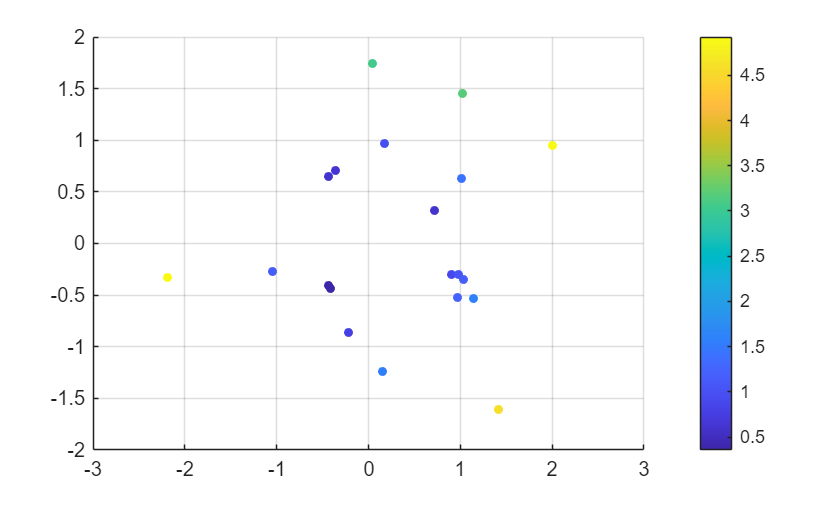

scatter3(points(:,1),points(:,2),values,20,values,"filled")
hold on
clbr = colorbar;
view([360.00 90.00])
hold off

rtree = fitrtree([points(:,1),points(:,2)],values)

rtree =   RegressionTree
             ResponseName: 'Y'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 20


  Properties, Methods


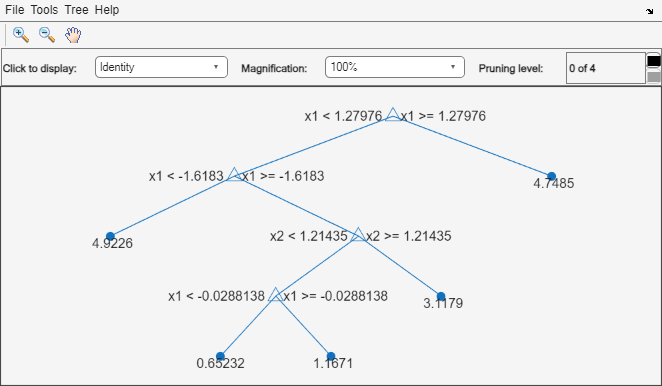

view(rtree,'Mode','graph')

view(rtree)


Decision tree for regression
1  if x1<1.27976 then node 2 elseif x1>=1.27976 then node 3 else 1.75365
2  if x1<-1.6183 then node 4 elseif x1>=-1.6183 then node 5 else 1.42088
3  fit = 4.74853
4  fit = 4.92258
5  if x2<1.21435 then node 6 elseif x2>=1.21435 then node 7 else 1.2149
6  if x1<-0.0288138 then node 8 elseif x1>=-0.0288138 then node 9 else 0.961162
7  fit = 3.11794
8  fit = 0.652323
9  fit = 1.16705



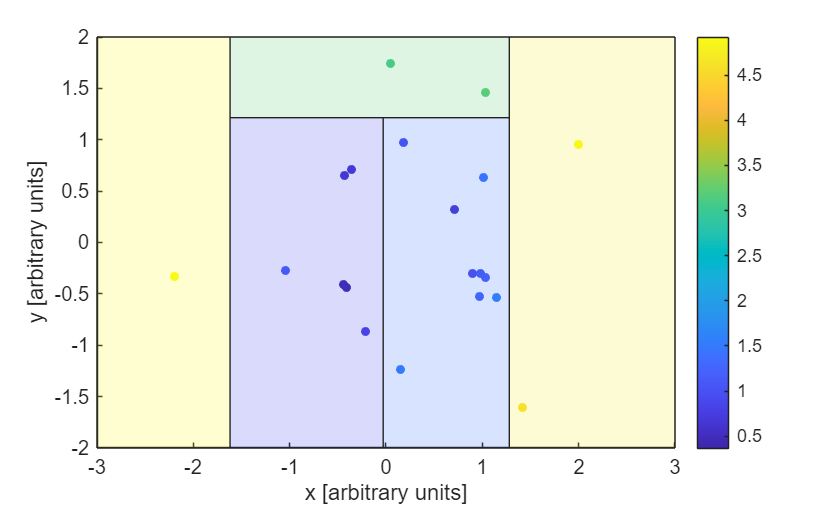

% manuall plotting of rtree on a scatter to show efficacy
scatter(points(:,1),points(:,2),20,values,"filled")
%scatter(points(:,1),points(:,2),20,values_old,"filled",AlphaData=0)
clbr = colorbar;
hold on 
xlim([-3,3])
ylim([-2 2])
ax = gca();
cmap = ax.Colormap;
%xline(1.27976)
     % min   max max  min |  min min max max  
patch([1.27976 3 3 1.27976], [-2 -2 2 2], getcolour(4.7485,cmap,values),'FaceAlpha',.2)
%xline(-1.6183)
patch([-3 -1.6183 -1.6183 -3], [-2 -2 2 2], getcolour(4.9226,cmap,values),'FaceAlpha',.2)
%yline(1.21435)
patch([-1.6183 1.27976 1.27976 -1.6183], [1.21435 1.21435 2 2], getcolour(3.1179,cmap,values),'FaceAlpha',.2)
%xline(-0.0288138)
patch([-1.6183 -0.0288138 -0.0288138 -1.6183], [-2 -2 1.21435 1.21435], getcolour(.65232,cmap,values),'FaceAlpha',.2)
patch([-0.0288138 1.27976 1.27976 -0.0288138], [-2 -2 1.21435 1.21435], getcolour(1.1671,cmap,values),'FaceAlpha',.2)
xlabel('x [arbitrary units]')
ylabel('y [arbitrary units]')
hold off

% colour values for inkscape 
planeHeights = [4.7485,4.9226,3.1179,.65232,1.1671];
for i = 1:length(planeHeights)
    rgb255 = floor(255*getcolour(planeHeights(i),cmap,values));
    disp([num2str(planeHeights(i)),' = ',num2str(rgb255(1)),' ',num2str(rgb255(2)),' ',num2str(rgb255(3))])
end

4.7485 = 245 236 34
4.9226 = 249 250 20
3.1179 = 96 204 113
0.65232 = 71 76 239
1.1671 = 58 114 254


% complex tree
points = readmatrix('randomPointsComplexTree.txt');
values = points(:,1).^2 + points(:,2).^2

values =     2.0198
    0.5861
    2.5593
    0.3386
    0.4491
    0.8805
    3.8743
    3.8198
    0.3278
    0.8314
    0.2344
    2.9283
    0.7110
    1.1719
    0.0883


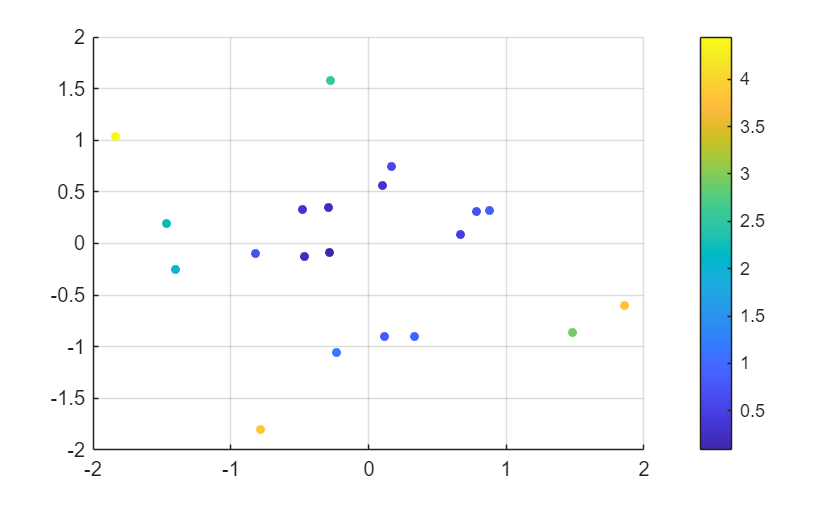

scatter3(points(:,1),points(:,2),values,20,values,"filled")
hold on
clbr = colorbar;
view([360.00 90.00])
hold off

rtree = fitrtree([points(:,1),points(:,2)],values)

rtree =   RegressionTree
             ResponseName: 'Y'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 20


  Properties, Methods


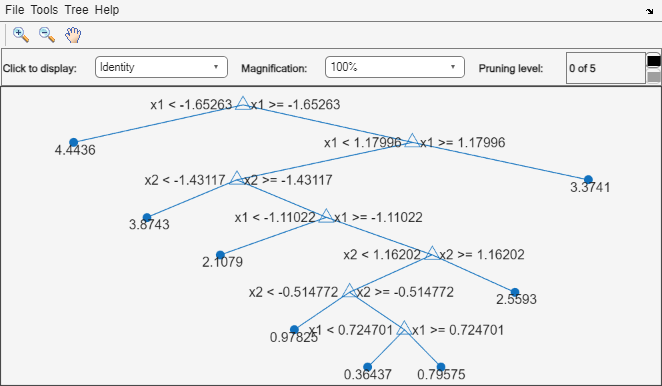

view(rtree,'Mode','graph')

view(rtree)


Decision tree for regression
 1  if x1<-1.65263 then node 2 elseif x1>=-1.65263 then node 3 else 1.46412
 2  fit = 4.44362
 3  if x1<1.17996 then node 4 elseif x1>=1.17996 then node 5 else 1.3073
 4  if x2<-1.43117 then node 6 elseif x2>=-1.43117 then node 7 else 1.06416
 5  fit = 3.37407
 6  fit = 3.87426
 7  if x1<-1.11022 then node 8 elseif x1>=-1.11022 then node 9 else 0.888524
 8  fit = 2.10795
 9  if x2<1.16202 then node 10 elseif x2>=1.16202 then node 11 else 0.71432
10  if x2<-0.514772 then node 12 elseif x2>=-0.514772 then node 13 else 0.572401
11  fit = 2.55928
12  fit = 0.978251
13  if x1<0.724701 then node 14 elseif x1>=0.724701 then node 15 else 0.450645
14  fit = 0.36437
15  fit = 0.795749



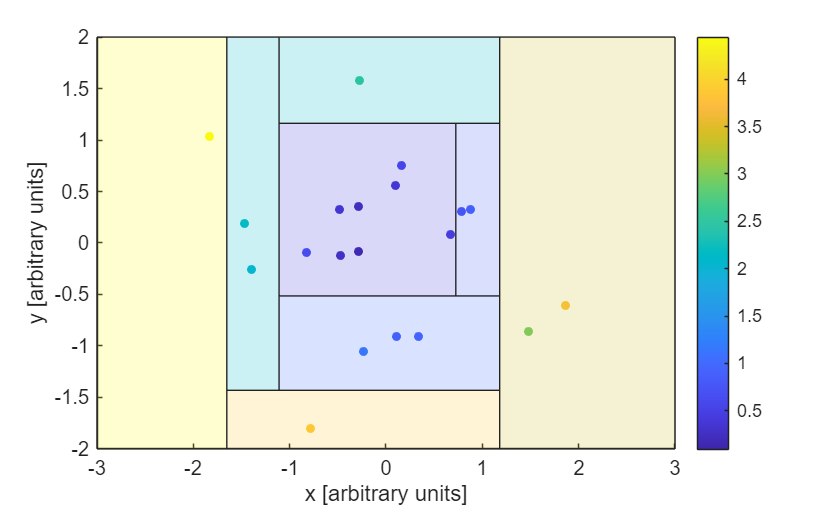

% manuall plotting of rtree on a scatter to show efficacy
scatter(points(:,1),points(:,2),20,values,"filled")
%scatter(points(:,1),points(:,2),20,values_old,"filled",AlphaData=0)
clbr = colorbar;
hold on 
xlim([-3,3])
ylim([-2 2])
ax = gca();
cmap = ax.Colormap;
%xline(-1.65263)
     % min   max max  min |  min min max max  
patch([-3 -1.65263 -1.65263 -3], [-2 -2 2 2], getcolour(4.4436,cmap,values),'FaceAlpha',.2)
%xline(1.17996)
patch([1.17996 3 3 1.17996], [-2 -2 2 2], getcolour(3.37407,cmap,values),'FaceAlpha',.2)
%yline(-1.43117)
patch([-1.65263 1.17996 1.17996 -1.65263], [-2 -2 -1.43117 -1.43117], getcolour(3.8743,cmap,values),'FaceAlpha',.2)
%xline(-1.11022)
patch([-1.65263 -1.11022 -1.11022 -1.65263], [-1.43117 -1.43117 2 2], getcolour(2.1079,cmap,values),'FaceAlpha',.2)
%yline(1.16202)
patch([-1.11022 1.17996 1.17996 -1.11022], [1.16202 1.16202 2 2], getcolour(2.1079,cmap,values),'FaceAlpha',.2)
%yline(-0.514772)
patch([-1.11022 1.17996 1.17996 -1.11022], [-0.514772 -0.514772 -1.43117 -1.43117], getcolour(0.97825,cmap,values),'FaceAlpha',.2)
%xline(0.724701)
patch([-1.11022 0.724701 0.724701 -1.11022], [-0.514772 -0.514772 1.16202 1.16202], getcolour(0.36437,cmap,values),'FaceAlpha',.2)
patch([0.724701 1.17996 1.17996 0.724701], [-0.514772 -0.514772 1.16202 1.16202], getcolour(0.79575,cmap,values),'FaceAlpha',.2)
xlabel('x [arbitrary units]')
ylabel('y [arbitrary units]')
hold off

% colour values for inkscape 
%planeHeights = [4.7485,4.9226,3.1179,.65232,1.1671];
%for i = 1:length(planeHeights)
%    rgb255 = floor(255*getcolour(planeHeights(i),cmap,values));
%    disp([num2str(planeHeights(i)),' = ',num2str(rgb255(1)),' ',num2str(rgb255(2)),' ',num2str(rgb255(3))])
%end


function rgbcode = getcolour(planeHeight,cmap,values)
    rgbcode = cmap(floor(planeHeight/max(values).*length(cmap)),:);
end